%% main_sarsa.m - 算法 8.2: 基于值函数的 Sarsa
clear; close all; clc;

% === 1. 环境初始化 ===
x_len = 5; y_len = 5;
start = [1, 1]; final = [3, 4];
obs = [2,2; 3,2; 3,3; 2,4; 4,4; 2,5];

env = GridWorld(x_len, y_len, start, final, obs);

% === 2. 算法参数 ===
episodes = 30000;
max_steps = 1000;
alpha = 0.05;    % 学习率
gamma = 0.95;    % 折扣因子
epsilon = 0.2;   % 初始探索率

% 初始化 Sarsa Agent
basis_type = 'quadratic'; % 推荐使用 'quadratic' 或 'rbf' 以获得非线性能力
num_actions = length(env.Action_Space);
agent = SarsaValueAgent(x_len, y_len, num_actions, basis_type, alpha, gamma, epsilon);

% === 3. 训练主循环 (对应 Algorithm 8.2 伪代码) ===
fprintf('开始 Sarsa 训练 (%s Basis, %d Episodes)...\n', basis_type, episodes);

开始 Sarsa 训练 (quadratic Basis, 30000 Episodes)...


tic

stats_steps = []; % 记录每回合步数

for ep = 1:episodes
    % 衰减 Epsilon (可选，有助于后期收敛)
    if ep > episodes * 0.5
        agent.Epsilon = max(0.01, epsilon * 0.999^(ep - episodes*0.5));
    end

    % 3.1 初始化状态 S
    curr_coord = env.Start_State;
    curr_idx = env.coord2idx(curr_coord);
    
    % 3.2 根据策略选择动作 A (Algorithm 8.2: Choose a from s using policy)
    curr_action_idx = agent.choose_action(curr_coord);
    
    step_count = 0;
    
    % 3.3 循环直到目标状态
    while true
        step_count = step_count + 1;
        
        % A. 执行动作 A, 观测 R, S' (Algorithm 8.2: Take action a, observe r, s')
        [next_idx, reward, is_done] = env.step(curr_idx, curr_action_idx);
        next_coord = env.idx2coord(next_idx);
        
        % B. 根据策略选择动作 A' (Algorithm 8.2: Choose a' from s' using policy)
        % 注意：Sarsa 是 On-policy，这里选择的 next_a 就是实际要执行的动作，也用于更新
        next_action_idx = agent.choose_action(next_coord);
        
        % C. 更新值函数 (Algorithm 8.2: Update w)
        % w = w + alpha * [r + gamma * Q(s', a') - Q(s, a)] * grad
        agent.update(curr_coord, curr_action_idx, reward, next_coord, next_action_idx, is_done);
        
        % D. 状态跳转 S <- S', A <- A'
        curr_coord = next_coord;
        curr_idx = next_idx;
        curr_action_idx = next_action_idx;
        
        % 终止条件
        if is_done || step_count >= max_steps
            break;
        end
    end
    
    stats_steps = [stats_steps, step_count];
    
    if mod(ep, 500) == 0
        fprintf('Episode %d: Steps = %d, Epsilon = %.3f\n', ep, step_count, agent.Epsilon);
    end
end

Episode 500: Steps = 1000, Epsilon = 0.200
Episode 1000: Steps = 523, Epsilon = 0.200
Episode 1500: Steps = 1000, Epsilon = 0.200
Episode 2000: Steps = 1000, Epsilon = 0.200
Episode 2500: Steps = 1000, Epsilon = 0.200
Episode 3000: Steps = 779, Epsilon = 0.200
Episode 3500: Steps = 1000, Epsilon = 0.200
Episode 4000: Steps = 1000, Epsilon = 0.200
Episode 4500: Steps = 279, Epsilon = 0.200
Episode 5000: Steps = 1000, Epsilon = 0.200
Episode 5500: Steps = 406, Epsilon = 0.200
Episode 6000: Steps = 1000, Epsilon = 0.200
Episode 6500: Steps = 309, Epsilon = 0.200
Episode 7000: Steps = 1000, Epsilon = 0.200
Episode 7500: Steps = 1000, Epsilon = 0.200
Episode 8000: Steps = 25, Epsilon = 0.200
Episode 8500: Steps = 1000, Epsilon = 0.200
Episode 9000: Steps = 1000, Epsilon = 0.200
Episode 9500: Steps = 1000, Epsilon = 0.200
Episode 10000: Steps = 23, Epsilon = 0.200
Episode 10500: Steps = 1000, Epsilon = 0.200
Episode 11000: Steps = 1000, Epsilon = 0.200
Episode 11500: Steps = 1000, Epsilon = 

toc

历时 251.297502 秒。



%% === 4. 数据转换与可视化 ===
% Sarsa 学到的是 Q(s,a)，但 GridWorld 的 plot_3d_bar_chart 需要 V(s)。
% 我们定义 V(s) = max_a Q(s,a) (贪婪策略下的价值)

V_derived = zeros(env.State_Space_Size, 1);
Policy_derived = zeros(env.State_Space_Size, 1);
Policy_Prob_Matrix = zeros(env.State_Space_Size, num_actions);

for i = 1:env.State_Space_Size
    coord = env.idx2coord(i);
    
    % 获取该状态下所有动作的 Q 值
    q_vals = agent.get_all_q_values(coord);
    
    % V(s) = max Q(s, a)
    [max_val, best_action] = max(q_vals);
    V_derived(i) = max_val;
    
    % 记录最优策略 (用于确定性绘图)
    Policy_derived(i) = best_action;
    
    % 构建概率矩阵 (用于 plot_policy_matrix)
    % 这里展示贪婪策略：最优动作概率为1，其余为0
    % (或者你可以用 softmax 使得显示更平滑)
    probs = zeros(1, num_actions);
    probs(best_action) = 1; 
    Policy_Prob_Matrix(i, :) = probs;
end

%% === 5. 调用 GridWorld 绘图接口 ===

% 5.1 绘制导出的状态价值 V(s)
fprintf('绘制状态价值 V(s) = max Q(s,a)...\n');

绘制状态价值 V(s) = max Q(s,a)...


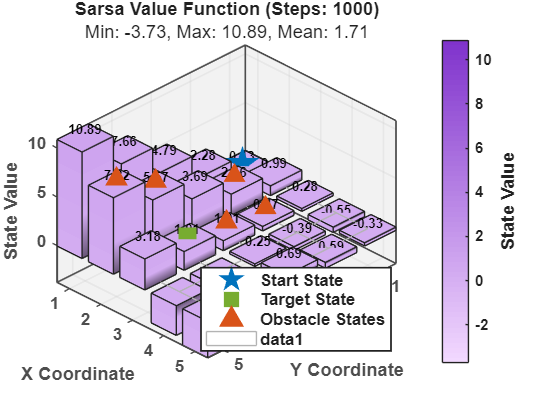

env.plot_3d_bar_chart(V_derived);
title(['Sarsa Value Function (Steps: ' num2str(mean(stats_steps(end-100:end))) ')']);

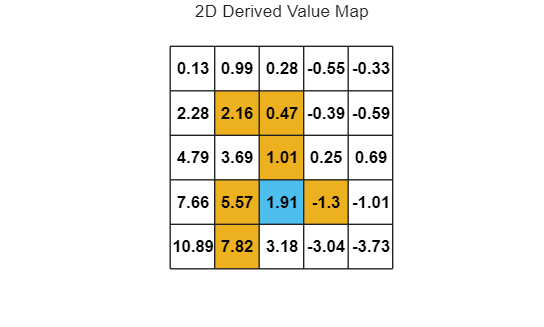


% 5.2 绘制 2D 价值分布
env.plot_values(V_derived);
title('2D Derived Value Map');


% 5.3 绘制策略流场 (Probabilistic)
fprintf('绘制策略流场...\n');

绘制策略流场...


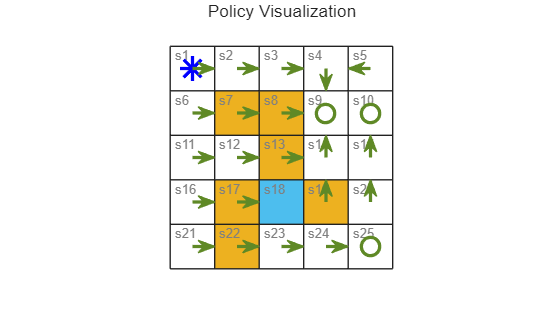

env.plot_policy_matrix(Policy_Prob_Matrix);

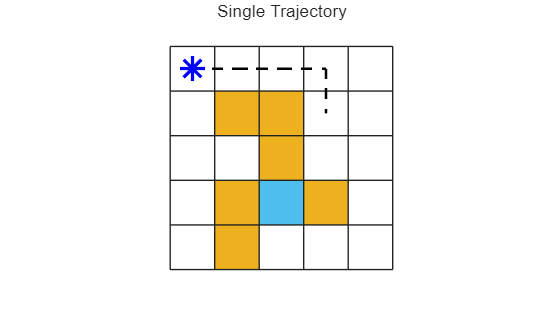


% 5.4 绘制最优路径轨迹
% 生成一条测试轨迹
test_history = [env.coord2idx(env.Start_State)];
curr = env.Start_State;
for k=1:30
    a_idx = agent.choose_action(curr); % 这里虽然有 epsilon，但测试时通常设为0，或者接受随机性
    [n_idx, ~, d] = env.step(env.coord2idx(curr), a_idx);
    test_history = [test_history, n_idx];
    if d, break; end
    curr = env.idx2coord(n_idx);
end
env.plot_trajectory(test_history);

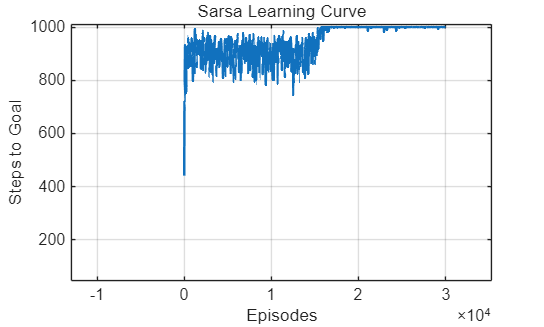


% 5.5 绘制收敛曲线
figure('Name', 'Training Progress', 'Color', 'w');
plot(smoothdata(stats_steps, 'movmean', 50), 'LineWidth', 1.5);
xlabel('Episodes'); ylabel('Steps to Goal');
title('Sarsa Learning Curve'); grid on;